# Functions

The basic function declaration is as follows:

`function [out1,out2,...,outn] = funcname(in1, in2,...,inm)`

It must be the first executable line in the file. Here `in1, in2, ..., inm` are the *input arguments* and `out1, out2, ..., outn` are the *output arguments*. If there is only one output we don't need the brackets:

`function out = funcname(in1,in2,...,inm)`

A function with no output arguments is declared as:

`function funcname(in1, in2,...,inm)`

A function with no input arguments is declared as:

`function [out1,out2,...,outn] = funcname`

## Writing a function

The m-file must have the same name as the function, so the following function is saved in the file `pcirclefcn.m`

`function [r, X, Y1, Y2] = pcirclefcn(r)`

`% PCIRCLEFCN draws a circle with radius r`

`%`

`% [r, X, Y1, Y2] = pcirclefcn(r) plots the circle and returns`

`% the radius r and the X, Y1, and Y2 coordinates.`

`X = -r:0.01:r;          % generate the x-coordinates`

`Y1 = sqrt(r^2 - X.^2);  % generate top half of circle`

`Y2 = -sqrt(r^2 - X.^2); % generate bottom half of cirlce`

`clf                     % clear the figure window`

`plot(X, Y1)             % plot the top half of the circle`

`hold on                 % hold the previous plot`

`plot(X, Y2)             % plot the bottom half of the circle`

`axis equal              % make the axes the same length`

`grid on                 % put grid lines on the figure`

`% Generate the text string for the title`

`titlestr = ['Circle with radius r = ', num2str(r)];`

`title(titlestr)         % add the title to the plot`

The first line in this m-file declares this program to be a function. All variables used in a function are local to the function. This means these variables are not in the Command Window workspace, but they can be accessed using the function?s input and output arguments. In this example, the function `pcirclefn` has one input argument, `r`, the radius of the circle, and the value of `r` is specified when the function is called. The function also has four output arguments `r, X, Y1, and Y2`.

The first comment line is called the H1-line. It gives a short, one line description of the function. On the H1-line the name of the function is all upper case to distinguish it from the descriptive text. This also causes it to print as bold in command window when `help` is called. The comments after the H1-line give a more detailed description of the function. Use Matlab's documentation as a model for your own functions.

Issuing the `help`-command prints the H1-line and the following comment block in the command window.

help pcirclefcn

  pcirclefcn draws a circle with radius r
   
  [r, X, Y1, Y2] = pcirclefcn(r) plots the circle and returns
  the radius r and the X, Y1, and Y2 coordinates.



Plots a circle of radius 1.

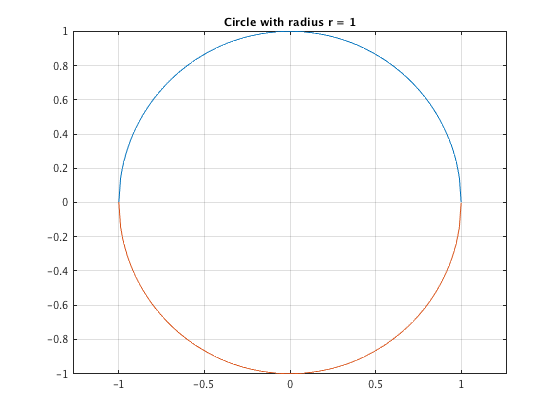

a = 1; pcirclefcn(a);

The radius can be directly specified.

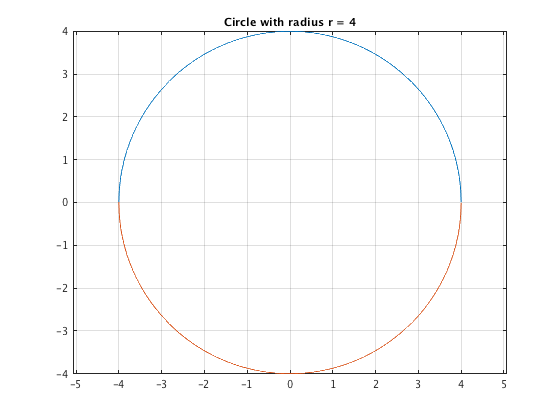

pcirclefcn(4);

The input can be an expression.

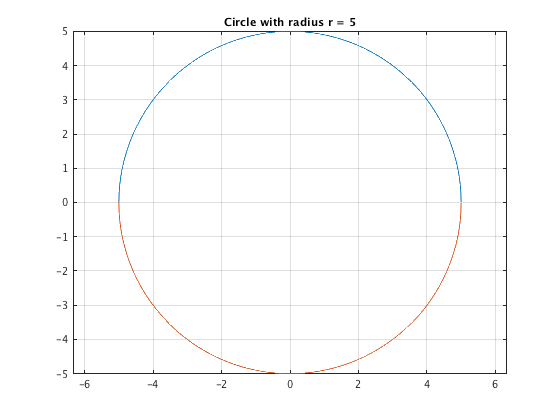

b = 3; pcirclefcn(2*b-1);

Without the semicolon the value of the first output variable is returned.

ans = 3

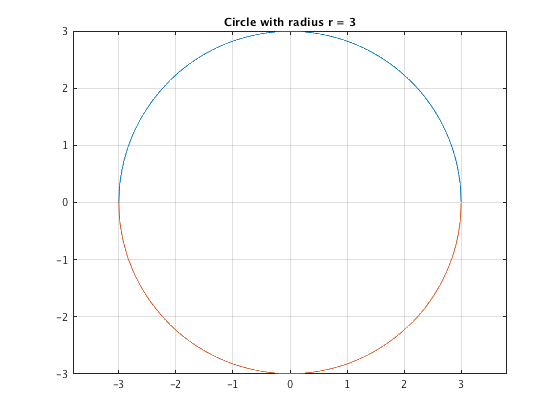

pcirclefcn(3)

Any variables used in the function are local to that function. Here `r` has no value.

clear, pcirclefcn(3);

who


Your variables are:

ans  



The return values are stored into the variables r, X, Y1 and Y2.

[r, X, Y1, Y2] = pcirclefcn(1);

who


Your variables are:

X    Y1   Y2   ans  r    



Plots the top half of the circle.

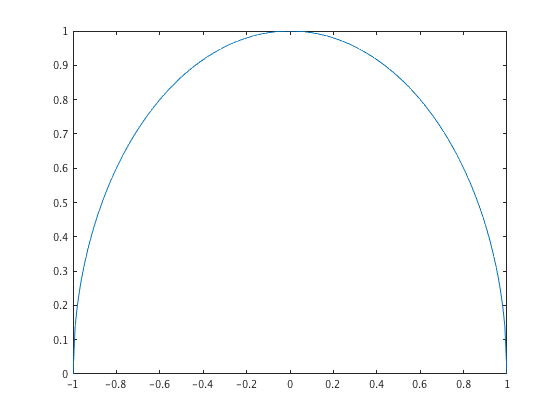

clf, plot(X, Y1)

Variable names can be different in the Command Window workspace.

[a, b, c, d] = pcirclefcn(4);

Plots the top half of the circle.

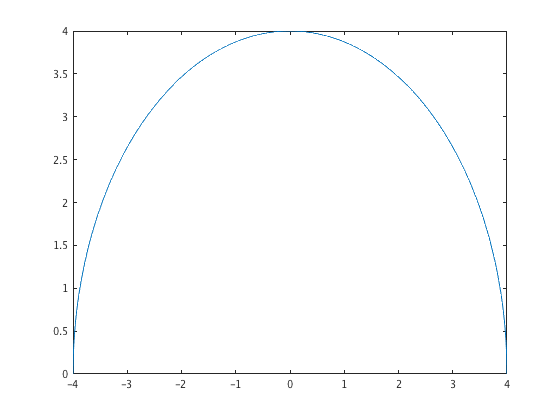

clf, plot(b, c);

Not all output arguments have to be used. Here only `r` and `X` are assigned to. Y1 and Y2 don't have values

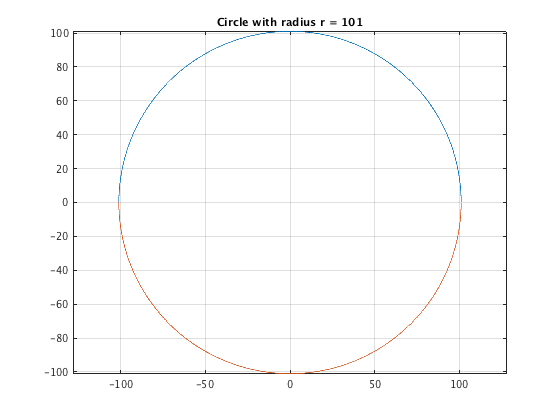

clear, [r, X] = pcirclefcn(101);

who


Your variables are:

X  r  



Unused output arguments can be indicated with the symbol tilde `~`. Here only X and Y2 are assigned to. This works only starting from Matlab version 7.9 (R2009b).

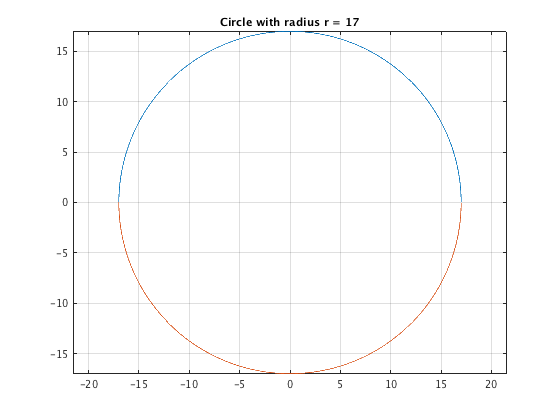

clear, [~, X, ~, Y2] = pcirclefcn(17);

who


Your variables are:

X   Y2  



## Recursive functions

A recursive function is a function that calls itself. The prototypical recursive function is the `factorial`, which satisfies the recursion: `factorial(0) = 1, factorial(n) = n*factorial(n - 1)`. We can write this almost as is into a Matlab function, see at the end of the file.

There the test `if n == 0` is the stopping criterion where the recursion stops. Every recursive function must have a stopping criterion, otherwise the recursive calls go on forever leading to the program crashing.

[myfactorial(0), myfactorial(5)]

ans =      1   120


## Function handles and anonymous functions

Function handles are a sort of pointer to a function, which can passed into and returned from other functions.

Function handles are created simply by typing `@` before the function name. You call the function by means of the handle just like with its name.

h = @sin

h = function_handle with value:
    @sin


h(pi/2)

ans = 1

Function handles are of class `function_handle`.

class(h)

ans = 'function_handle'

isa(h, 'function_handle')

ans = logical
   1


`func2str` converts a handle to a string and `str2func` converts a string to a handle.

func2str(h)

ans = 'sin'

str2func('sin')

ans = function_handle with value:
    @sin


The command `integral` computes an approximation to the integral from 0 to $\pi$.

integral(h, 0, pi)

ans = 2.0000

integral(@cos, 0, pi)

ans = 1.2490e-16

The argument function must be vectorized, i.e., accept an array as an argument.

integral(@(x)x.^2, 0, 1)

ans = 0.3333

The command `fplot` plots a function using a handle. 

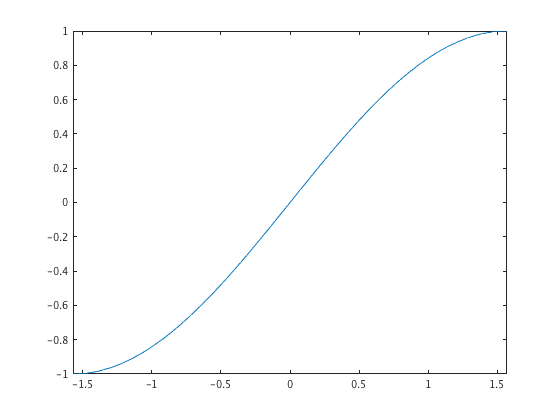

clf, fplot(h, [-pi/2 pi/2])

**Anonymous functions**

Anonymous functions are expression of the form `@(arg1,arg2,...) body`, where `body` consists of a single Matlab expression, loops or conditional statements are not allowed.. Anonymous functions are otherwise just like ordinary functions, except they are not stored in a program file. Here we set `f` to a function handle to the anonymous function `@(x) sin(x) + sin(sqrt(2)*x)`.

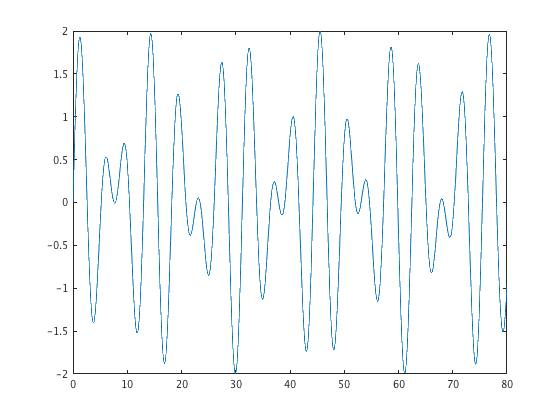

f = @(x) sin(x) + sin(sqrt(2)*x);
clf, fplot(f, [0 80])

An anonymous function can be passed as an argument to a function. The  argument to MeshDensity gives the number of evaluation points.

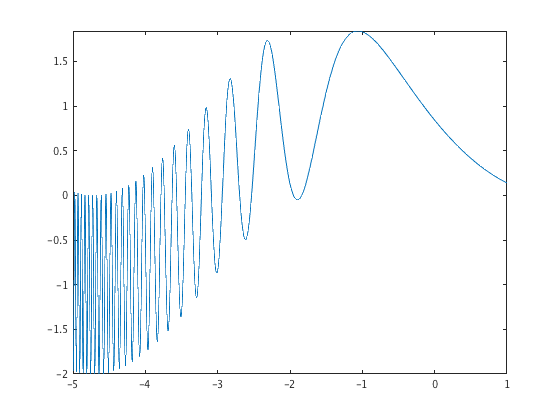

clf, fplot(@(x)sin(x+exp(-x))-sin(x), [-5, 1], 'MeshDensity', 50)

An anonymous function captures the current values of variables used in the function body but not occuring in the argument list.

n = 4; npow = @(x) x^n

npow = function_handle with value:
    @(x)x^n


npow(2)

ans = 16

The `n` in `npow` is still 4.

n = 5; npow(2)

ans = 16

## Local functions (subfunctions)

A function m-file can contain the definition of several functions. The first function in a file is the primary function or main function and the file name should always be the name of the primary function. Following the primary function there can be several local functions. A typical situation is shown below.

`function y = main(args)`

`    Code for main`

`end % Optional`

`function y1 = sub1(args1)`

`   Code for sub1`

`end % Optional`

`function y2 = sub2(args2)`

`   Code for sub2`

`end % Optional`

Here `sub1` and `sub2` are local functions of main, which is the primary function since it is the first function in the file (so the file name should be `main.m`). None of the functions can access the local variables of the other functions. A local function can be called only from the primary function and other local functions in the same file. Therefore local functions are not visible outside the file. The `end` statements at the end of the functions are not mandatory (except in scripts), but adding them can improve the clarity of the code.

The next example shows how to vectorize a function with conditional statements by using the command `arrayfun` and a local function.

`function s = step1(t)`

`% STEP1  A step function.`

`assert(isfloat(t), 'The argument must be a floating point array.')`

`s = arrayfun(@stepaux, t);`

`function s = stepaux(t) % A local function`

`if t < 1`

`    s = -1;`

`else`

`    s = 3;`

`end`

Note that the output of `step1` has the same shape (the number of rows, columns, and dimensions) as the input.

Now step1 works with scalars...

step1(0)

ans = -1

step1(2)

ans = 3

... vectors...

step1(-1:2)

ans =     -1    -1     3     3


...matrices...

A = reshape(-2:3, 2, 3)

A =     -2     0     2
    -1     1     3


step1(A)

ans =     -1    -1     3
    -1     3     3


...and multidimensional arrays.

B = randi([-5 5], 2, 2, 2)

B = B(:,:,1) =

     4    -5
    -1     2


B(:,:,2) =

     5     2
     3    -3


step1(B)

ans = ans(:,:,1) =

     3    -1
    -1     3


ans(:,:,2) =

     3     3
     3    -1


Next, another way to vectorize the step function above. First we initialize the output to be the same size and shape as the input and then we go through the array in a for-loop using linear indexing. The function `numel` returns the number of elements in an array. The name of the local function can be the same as in `step1`, since the name is not visible outside the file.

`function s = step2(t)`

`% STEP2  A step function.`

`assert(isfloat(t), 'The argument must be a floating point array.')`

`s = zeros(size(t));`

`for k = 1:numel(t)`

`    s(k) = stepaux(t(k));`

`end`

`function s = stepaux(t) % A local function`

`if t < 1`

`    s = -1;`

`else`

`    s = 3;`

`end`

`step2` works just like `step1`.

step2([0 3; -1 4])

ans =     -1     3
    -1     3


Plotting is easy since we can call `step2` with a vector argument.

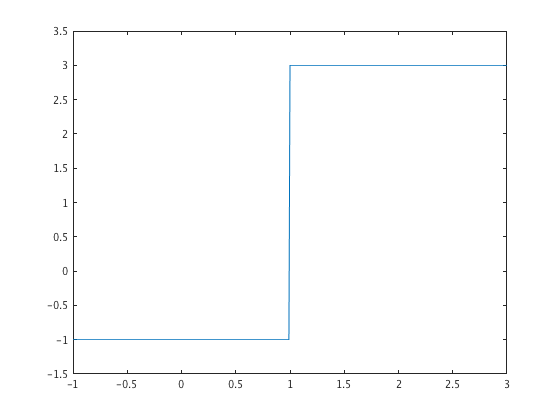

t = -1:0.01:3;
clf, plot(t, step2(t)), axis([-1 3 -1.5 3.5])

Same with numerical integration.

integral(@step2, -1, 2)

ans = 1.0000

In this case the for-loop is much faster than `arrayfun`.

A = randn(1000);

tic; B1 = step1(A); toc

Elapsed time is 3.411034 seconds.


tic; B2 = step2(A); toc

Elapsed time is 0.037578 seconds.


The results are equal.

isequal(B1, B2)

ans = logical
   1


## Nested functions

A nested function is a function that is defined inside another function. A typical situation is shown below.

`function y = outer(args)`

`   Code for outer`

`function y1 = nested1(args1)`

`   Code for nested1`

`end`

`function y2 = nested2(args2)`

`   Code for nested2`

`end`

`end % outer`

Here `nested1` and `nested2` are nested functions of `outer` . Both `nested1` and `nested2` can access the local variables of `outer` . The function `outer` can also access the local variables of `nested1` and, `nested2`, but this usually not a good idea. All functions must be ended with `end`, including possible local functions.

The function `outer` can call `nested1` and `nested2`, which can call each other. The functions `nested1` and `nested2` cannot be called from outside `outer`. However, if the outer function returns a handle to a nested function, it can be called from anywhere using the handle.

In the following example `make_adder` (at the end of the file) returns a handle to the nested function `adder` that increments its argument by `incr`. Each returned instance of `adder` has its very own copy of `incr`.

The function `add1` increments its argument by one.

add1 = make_adder(1)

add1 = function_handle with value:
    @make_adder/adder


add1(101)

ans = 102

The function `add5` increments its argument by five.

add5 = make_adder(5)

add5 = function_handle with value:
    @make_adder/adder


add5(101)

ans = 106

We can do the same with anonymous functions.

adder_make = @(incr) @(x) x + incr

adder_make = function_handle with value:
    @(incr)@(x)x+incr


Increment by one

adder1 = adder_make(1)

adder1 = function_handle with value:
    @(x)x+incr


adder1(101)

ans = 102

Increment by five

adder5 = adder_make(5)

adder5 = function_handle with value:
    @(x)x+incr


adder5(101)

ans = 106

## Optional arguments

A function can have required and optional input and output arguments. The function `foo` at the end of the file has two required and two optional arguments. The function `narginchk` checks that there are at least two and at most four input arguments. Calling the function with less than 2 or more than 4 arguments produces an error message. The function `nargin` returns the number of input arguments the function was called with. The missing arguments are given default values.

The input argument `d` has the default value 17.

foo(1, 2, 3)

ans = 23

The argument `c` has the default value 5 and the argument `d` has the default value 17.

foo(1, 2)

ans = 25

## Functions with variable number of arguments

Cell arrays are useful in writing functions that can take an arbitrary number of arguments. The function `gmean` at the end of the file computes the geometric mean of its arguments. If there are two output arguments, the function returns the arithmetic mean in the second one.

The argument `varargin` is a cell array containing all the input arguments. It has to be the last in the argument list, after the named input arguments (there are none in this example).

The function `nargoutchk` checks that there are either one or two output arguments.

The function `nargout` returns the number of output arguments the function was called with.

The expression `varargin{:}` is a comma separated list of the input arguments and `[varargin{:}]` is a vector containing the input arguments.

One output argument.

g = gmean(1, 2)

g = 1.4142

Two output arguments.

[g, m] = gmean(1, 2, 3)

g = 1.8171

m = 2

As a second example we write a more convenient line plotting, where we don't have to separate the x- and y-coordinates into separate vectors. Here `varargin` allows us to pass an arbitrary number of properties to the `line` function.

drawline = @(from,to,varargin) line([from(1), to(1)], [from(2), to(2)],varargin{:})

drawline = function_handle with value:
    @(from,to,varargin)line([from(1),to(1)],[from(2),to(2)],varargin{:})


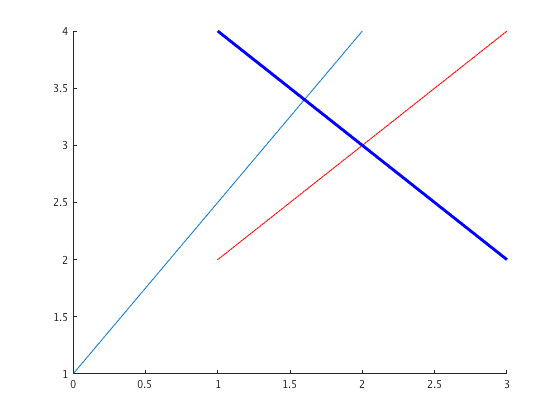

clf
drawline([0 1], [2 4])
drawline([1 2], [3 4], 'Color', 'r')
drawline([1 4], [3 2], 'Color', 'b', 'LineWidth', 3)

function f = myfactorial(n)
% MYFACTORIAL computes the factorial function.
    
    if n == 0
        f = 1; % Recursion stops
    else
        f = n*myfactorial(n - 1);
    end
end

function fhandle = make_adder(incr)
% MAKE_ADDER  Returns a function that increments its argument by a given amount.

    fhandle = @adder;

    function s = adder(x)
      	s = x + incr;
    end
end

function y = foo(a, b, c, d)

    narginchk(2, 4);
    
    if nargin < 4
    	d = 17;
    end
    
    if nargin < 3
    	c = 5;
    end
    
    y = a + b + c + d;
end

function [g, m] = gmean(varargin)

    n = length(varargin);
    assert(n > 0, 'Need at least one argument.')
    nargoutchk(0, 2);
    
    args = [varargin{:}];
    tmp = prod(args);
    g = tmp^(1/n);
    
    if nargout == 2
        m = sum(args)/n;
    end
end